# SNR Explained

Signal to noise ratio (SNR) is described in the literature by many formulas. To get an inuitive feel for what sequence changes will increase or decrease SNR, it is useful to understand the underlying effects. 

The measured image is the true data with noise superimposed. 

In complex images, the noise is Gaussian distributed separately in the real and imaginary channels and with zero mean and a certain variance, or standard deviation (variance is the square of standard deviatin). The variance is the measure of the noise. The SNR is the ratio of the true signal to the standard deviation of the noise. (We usually view magnituge images where the noise then has a Rician distribution.)

The fundamental sources of noise are the electronics and the body itself. In some papers, these are characterised by electrical resistances which may be useful in coil design but doesn't help when considering sequences. Also, in the early days at lower field strengths, electrical noise dominated, but at 1.5T+, body noise dominates.

The key mental picture I use, is of a warm body with many magentic dipoles all transmitting at all frequencies at all times. This noise is 'white' (spans equally all frequencies we are interesetd in). During receive, a coil gets true signal only from the excited slice or slab, but it receives noise from everywhere it 'sees'.

The amount of noise a coil lets in is determined by its bandwidth. A faster readout needs a greater range of frequencies and thus a larger bandwidth and letting in more noise. 

N = 5000 ; % number of samples
stdn = 7 ; % noise standard deviation i.e. sqrt(variance)
zsig = 30 ; % signal strength, 'z' to remind it can be complex.
snr1 = zsig / stdn ; % SNR
disp(['SNR: ',num2str(snr1), ' (',num2str(zsig),' / ', ...
                                  num2str(stdn),')'])

SNR: 4.2857 (30 / 7)



% To get distribution with correct standard deviation, multiply
%  output from randn (which assumes zero mean and std of 1) 
%  by std required.
% Complex noise - Gaussian in real and imaginary parts
zn = randn(N,1).*stdn +1i*randn(N,1).*stdn ; 

zspn = zsig + zn ; % measured is true signal plus complex noise
zair = zn ;  % in 'air' with no true signal

% Fit Rayleigh distribution to abs 'air' (no true signal)
% The B corresponds to the std of the underlying Gaussian
pdRa = fitdist(abs(zair),'Rayleigh') 

pdRa =   RayleighDistribution

  Rayleigh distribution
    B = 6.88995   [6.79578, 6.98679]



% Fit Rician to abs of true signal plus noise
pdRi = fitdist(abs(zspn),'Rician')

pdRi =   RicianDistribution

  Rician distribution
        s = 30.0431   [29.8455, 30.2407]
    sigma = 6.92401   [6.7855, 7.06535]


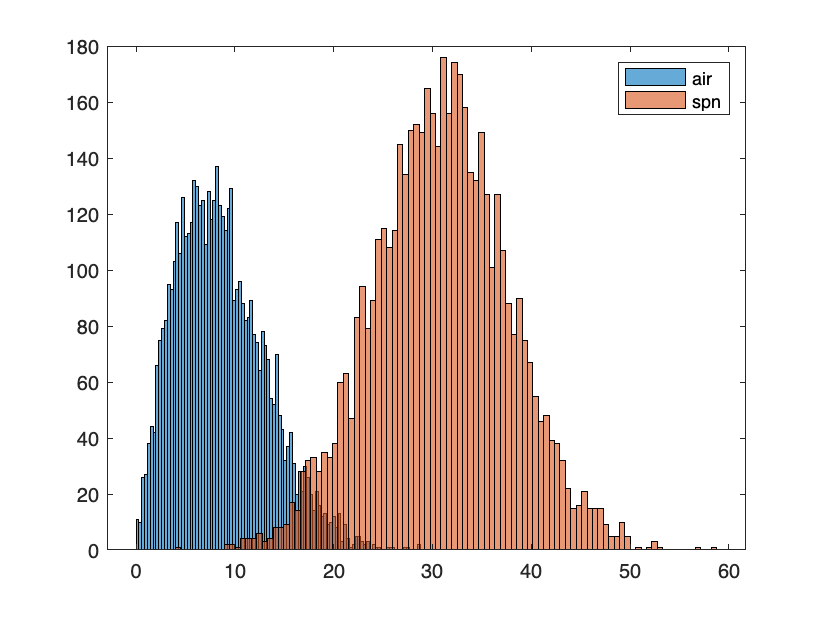


figure
nbins=100;
histogram(abs(zair),nbins,'DisplayName','air'), hold on
histogram(abs(zspn),nbins,'DisplayName','spn')
legend

### Adding Noise to K-space

In simulation, we may simulate k-space, say from multiple coils, and then need to add noise prior to reconstruction. (Adding noise once to the original image would not be correct). The total noise power should be the same in the image or k-space domain (Parseval's theorem), but FFT scaling may complicate this? For a given image SNR, what is the std of the noise we should add?

To each image pixel, we add noise drawn from a distribution with zero mean and a certain std. To each k-space point, we should add noise also with zero mean, and a std scaled by the same as used in the FT from image to k-space.

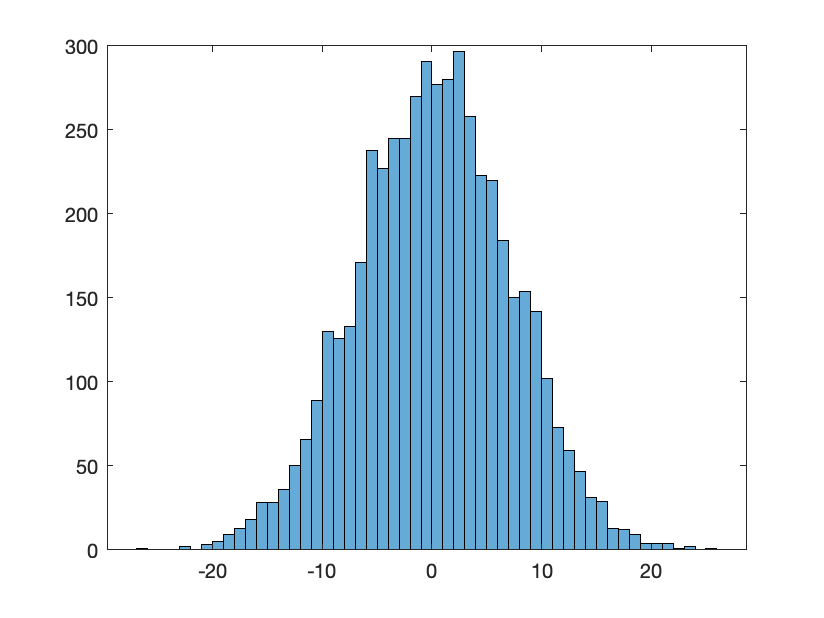

kn = (randn(N,1).*stdn +1i*randn(N,1).*stdn )/sqrt(N);  % no scale in i2k (uses fft)

inn = i2k(kn);
figure
histogram(real(inn),nbins)

pdRaN = fitdist(abs(inn),'Rayleigh') 

pdRaN =   RayleighDistribution

  Rayleigh distribution
    B = 6.96454   [6.86935, 7.06243]


If the upcoming transform (e.g. `k2i`, which uses `ifft` and divides by `N`) will divide by `N`, then multiply noise by `sqrt(N)`. If upcoing transorm does not, then divide by `sqrt(N)`. Heurisitic rule is divide by `sqrt(N)` then divide by scaling factor to be applied in transform? So for "balanced" as used in the DFT for LSQR, do nothing!

### Matching added k-space noise to image SNR

First determine from image the 'underlying' gaussian noise distribution. 

Compute equivalent gaussian distribution for 1 average.

### References

Dietrich JMRI 2007 [https://onlinelibrary.wiley.com/doi/pdf/10.1002/jmri.20969](https://onlinelibrary.wiley.com/doi/pdf/10.1002/jmri.20969) 

MATLAB Help on:

Rayleigh Distribution (and many others, see `fitdist`)